## Raman Intensity for Arbitrary Crystal Rotation and Linearly Polarized Light in the xy-Plane

### Calculation of Raman Intensities as a Function of Euler Rotation Angles

**insert Raman tensors:**

syms theta phi1 Phi phi2 x a b c d real

% Define the Jones matrix (2D polarization on x-y plane)
J = [1, 0; 0, exp(1i * x)];

% Define a general 3x3 Raman tensor
alpha = [a, 0, 0; 0, a, 0; 0, 0, b];
E_x = [c, 0, 0; 0, -c, d; 0, d, 0];
E_y = [0, -c, -d; -c, 0, 0; -d, 0, 0];

% Define 3D rotation matrices for Z-X-Z Euler rotation and Jones matrix
R_Z1 = [cos(phi1), -sin(phi1), 0; sin(phi1), cos(phi1), 0; 0, 0, 1];
R_X = [1, 0, 0; 0, cos(Phi), -sin(Phi); 0, sin(Phi), cos(Phi)];
R_Z2 = [cos(phi2), -sin(phi2), 0; sin(phi2), cos(phi2), 0; 0, 0, 1];
R_J = [cos(phi1), -sin(phi1); sin(phi1), cos(phi1)];

**insert angles phi1, Phi, phi2 and x if known:**

% Substitute x in Jones matrix
J = subs(J, x, 0);

% Substitute angles in rotation matrices to match lab frame to crystal frame
%R_Z1 = subs(R_Z1, phi1, 0);
R_X = subs(R_X, Phi, 0);
R_Z2 = subs(R_Z2, phi2, 0);

% Rotated Jones Matrix R_J J R_J^T
final_J = R_J * J * R_J.'; %R_J^T=R_J.'

% Full rotation matrix in 3D
R_total = simplify(R_Z1 * R_X * R_Z2);

% Define incident and scattered polarization vectors in 2D e_i = e_s
e_i = [cos(theta); sin(theta)];
e_s = [cos(theta); sin(theta)];

% Rotate Raman tensor (Z-X-Z)
alpha_rotated = R_total * alpha * R_total.';
E_x_rotated = R_total * E_x * R_total.';
E_y_rotated = R_total * E_y * R_total.';

% Take 2D from 3D Raman tensor
alpha_rotated_2d = alpha_rotated(1:2, 1:2);
E_x_rotated_2d = E_x_rotated(1:2, 1:2);
E_y_rotated_2d = E_y_rotated(1:2, 1:2);

% Compute square root of Raman scattering intensity using Jones formalism
sqrt_I_alpha = simplify(e_i.' * final_J * alpha_rotated_2d * final_J * e_s);
sqrt_I_x = simplify(e_i.' * final_J * E_x_rotated_2d * final_J * e_s);
sqrt_I_y = simplify(e_i.' * final_J * E_y_rotated_2d * final_J * e_s);

% Compute Raman scattering intensity
I_alpha = sqrt_I_alpha * conj(sqrt_I_alpha);
I_alpha = simplify(subs(I_alpha, exp(2i*x), cos(2*x) + 1i*sin(2*x)));
I_alpha = simplify(subs(I_alpha, exp(-2i*x), cos(2*x) - 1i*sin(2*x)));
I_alpha = simplify(real(I_alpha));  % <--- this ensures no imaginary part

I_x = simplify(expand(sqrt_I_x * conj(sqrt_I_x)));
I_x = simplify(subs(I_x, exp(2i*x), cos(2*x) + 1i*sin(2*x)));
I_x = simplify(subs(I_x, exp(-2i*x), cos(2*x) - 1i*sin(2*x)));
I_x = simplify(real(I_x));  % <--- this ensures no imaginary part

I_y = simplify(expand(sqrt_I_y * conj(sqrt_I_y)));
I_y = simplify(subs(I_y, exp(2i*x), cos(2*x) + 1i*sin(2*x)));
I_y = simplify(subs(I_y, exp(-2i*x), cos(2*x) - 1i*sin(2*x)));
I_y = simplify(real(I_y));  % <--- this ensures no imaginary part

I_E = simplify(expand(I_x + I_y));

% Display results
disp('I_alpha:');

I_alpha:


disp(I_alpha);

$$a^{2}$$

disp('I_x:');

I_x:


disp(I_x);

$$\frac{c^{2}\,\left(\cos\left(4\,\varphi_{1}-4\,\theta \right)+1\right)}{2}$$

disp('I_y:');

I_y:


disp(I_y);

$$-\frac{c^{2}\,\left(\cos\left(4\,\varphi_{1}-4\,\theta \right)-1\right)}{2}$$

disp('I_E:');

I_E:


disp(I_E);

$$c^{2}$$

### Fit Calculated Intensities to Raman Data

**choose the sample (folder), the peak (position) you want to fit, to which Ramn mode this peak corresponds and whether you want the plot to be cartesian or half-polar:**

% ====== Choose Sample: "Quartz", "aCalcite", or "cCalcite" ======
selected_folder = "Quartz";  
chosen_peak = 1163;  % choose peak position

% ====== Choose Mode: 'alpha'or 'E' ======
selected_mode = 'E';  

% ====== Choose Plot Type: "normal" or "half-polar" ======
plot_type = "half-polar";  

% ====== Read CSV ======
% Get the folder where the live script is saved
scriptPath = matlab.desktop.editor.getActiveFilename;
scriptDir = fileparts(scriptPath);

% Build your CSV file path relative to that
csv_file = fullfile(scriptDir, '..', 'data', selected_folder, 'normalized_peak_heights.csv');
T = readtable(csv_file, 'VariableNamingRule', 'preserve');

% Extract angles and corresponding intensities
angles = T.theta;

% Get the variable names from the table
col_names = T.Properties.VariableNames;

% Find the column name that starts with the chosen peak number
pattern = sprintf('%d cm', chosen_peak);  % e.g., '1091 cm'
matching_idx = find(contains(col_names, pattern), 1);

if isempty(matching_idx)
    error("No column found matching peak position %d cm⁻¹", chosen_peak);
end

column_name = col_names{matching_idx};

intensities = T.(column_name);

% Sort angles and corresponding intensities
[angles_sorted, sort_idx] = sort(angles);
theta_data = angles_sorted;
intensities_sorted = intensities(sort_idx);

% Choose expression based on selected_mode
switch selected_mode
    case 'alpha'
        selected_I = I_alpha;
    case 'E'
        selected_I = I_E;
    otherwise
        error('Invalid mode selected: choose "alpha", "x", or "y"');
end


% === Automatically extract symbolic parameters from the expression ===
% Get all free symbolic variables in selected_I
all_vars = symvar(selected_I);

% Remove theta (independent variable) from the list
fit_params_sym = setdiff(all_vars, theta);

% Sort for consistent order
fit_params_sym = sort(fit_params_sym);

% Create a function handle for numerical fitting
fit_handle_sym = matlabFunction(selected_I, 'Vars', {theta, fit_params_sym});

% Create numerical fitting function directly from symbolic expression
% Wrap into fitting function (convert degrees to radians)
fit_func = @(params, theta_deg) arrayfun(@(t) fit_handle_sym(deg2rad(t), params), theta_deg);

**insert initial guesses for the fit parameters, if you do not insert anything, the initial guess for all parameters is 1:**

% Define custom guesses for some parameters
custom_guesses = struct( ...
    'a', 3, ...
    'b', 6, ...
    'c', 1, ...
    'd', 1, ...
    'phi1', 0.9, ...
    'Phi', 0, ...
    'phi2', 0, ...
    'x', pi/4 ...
); % parameters that are not fittet are omitted automatically, 
% you do not have to comment them out

% Loop through fit_params_sym and assign guesses
initial_guess = zeros(1, numel(fit_params_sym));
for i = 1:numel(fit_params_sym)
    pname = char(fit_params_sym(i));
    if isfield(custom_guesses, pname)
        initial_guess(i) = custom_guesses.(pname);
    else
        initial_guess(i) = 1;  % fallback default
    end
end

% ====== Fit data ======
params_fit_cell = nlinfit(theta_data, intensities_sorted, fit_func, initial_guess);
params_fit = params_fit_cell;

% ====== Print fitted parameters ======
fprintf('Fitted parameters:\n');

Fitted parameters:


for k = 1:numel(fit_params_sym)
    pname = char(fit_params_sym(k));
    pval = params_fit(k);
    
    if contains(pname, 'phi') || contains(pname, 'Phi') || strcmp(pname, 'x')
        fprintf('  %s = %.4f rad (%.2f°)\n', pname, pval, rad2deg(pval));
    else
        fprintf('  %s = %.4f\n', pname, pval);
    end
end

  c = 0.7660



% ====== Generate fitted values ======
theta_fit = linspace(min(theta_data), max(theta_data), 200);
fit_values = fit_func(params_fit, theta_fit);

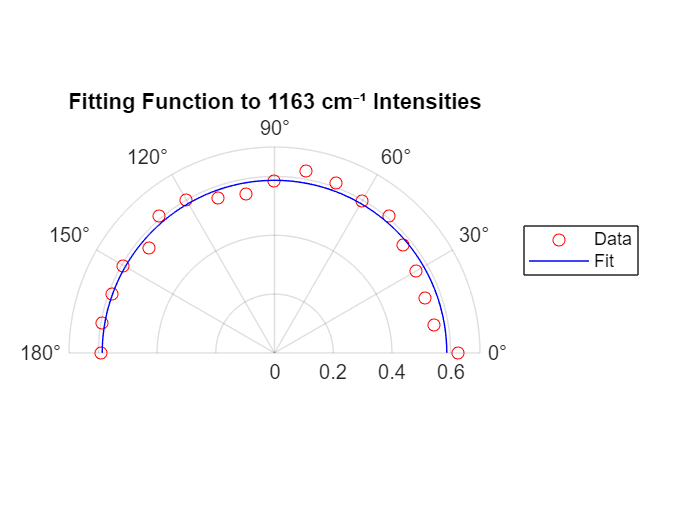

% ====== Plotting ======
switch plot_type
    case "normal"
        figure;
        scatter(theta_data, intensities_sorted, 'r', 'DisplayName', 'Data');
        hold on;
        plot(theta_fit, fit_values, 'b', 'DisplayName', 'Fit');
        xlabel('Rotation Angle (degrees)');
        ylabel('Intensity (arb units)');
        title(sprintf('Fitting Function to %d cm⁻¹ Intensities', chosen_peak));
        legend();
        grid on;
    
    case "half-polar"
        figure;
        polaraxes;
        hold on;
        polarplot(deg2rad(theta_data), intensities_sorted, 'ro', 'DisplayName', 'Data');
        polarplot(deg2rad(theta_fit), fit_values, 'b-', 'DisplayName', 'Fit');
        title(sprintf('Fitting Function to %d cm⁻¹ Intensities', chosen_peak));

        ax = gca;
        ax.ThetaLim = [0 180];
        ax.ThetaTick = 0:30:180;
        ax.ThetaTickLabel = {'0°','30°','60°','90°','120°','150°','180°'};
        legend();
        
    otherwise
        error("Invalid plot type! Choose 'normal' or 'half-polar'.");
end